# MATLAB Operations and Arrays

## Matrix laboratory

*MATLAB deals with arrays (matrices) of any type efficiently*

- It’s the competitive advantage of MATLAB

- So, it’s best to understand how to deal with the array in MATLAB

*Things to keep in mind*

In MATLAB, everything is an array

- numeric arrays

- character arrays

- cell arrays

- string arrays

With numeric arrays, standard operators (`*`|`/`) take on **very different **meanings when preceded by a '`.`'

The '`.`' indicates *'element by element' *operations

## Numerical Arrays

** Indexing**

- Numeric Arrays refer to *vectors* and any *higher dimensional matrices* two ways of referencing an array

- 2+ indices: specify row, column, …

- 1 index: runs down each column

a = [4,10,1,6,2; 8,1.2,9,4,25;7.2,5,7,1,11;0,0.5,4,5,56;23,83,13,0,10]

a =           4.00         10.00          1.00          6.00          2.00
          8.00          1.20          9.00          4.00         25.00
          7.20          5.00          7.00          1.00         11.00
             0          0.50          4.00          5.00         56.00
         23.00         83.00         13.00             0         10.00


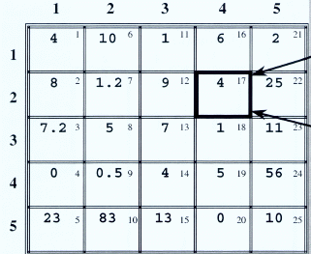

a(2,3)

ans =           9.00

a(11)

ans =           1.00

**Creating Arrays**

- Array elements must be enclosed by `[…]`

- Columns are separated by a <space> or` ,` 

- Rows are separated by a` ;`

A = [1,2,3; 4 5 6; 7,8 9]

A =           1.00          2.00          3.00
          4.00          5.00          6.00
          7.00          8.00          9.00


*MATLAB has a very special operator *`:`

- `: `saves typing when creating a regular array 

- `: ` is a place holder for a range of values

`array = start:interval:end`

A=1:9

A =           1.00          2.00          3.00          4.00          5.00          6.00          7.00          8.00          9.00


reshape(A,3,3)'

ans =           1.00          2.00          3.00
          4.00          5.00          6.00
          7.00          8.00          9.00


B=1:2:9

B =           1.00          3.00          5.00          7.00          9.00


**Combining Arrays**

- MATLAB makes it easy to combine (or *concatenate*) arrays

- *Just make sure the dimensions work out*

B = [1,3,7]

B =           1.00          3.00          7.00


[A B']

Error using horzcat
Dimensions of arrays being concatenated are not consistent.

[A;B]

**Array Operations**

MATLAB can operate *element by element *or matrix-wise depending on the syntax

*(this is where* *the* *‘*`.`*’ becomes vital)*

A*A
A.*A
A*B
A.*B
A.*B'

## Character Arrays

MATLAB treats every character in a character array as an individual element. Surround text with single quotation marks,` ' '`

g='test me'
g(3)

## String Arrays

MATLAB treats every *collection of characters *as an element. Surround text with double quotations marks, `" "`

h="test me"
h(1)

h2 = ["strings can", "be in arrays", "just like"; "numbers", "as long as ", "it's in matrix form"]

## Cell Array

- A cell array is a data type with indexed data containers called *cells*

- Each cell can contain any *type of data*

- Cell arrays are created using `{ } `NOT `[ ]`

C = {1,2,3;'one',"two",'three'}

**Indexing a Cell Array**

Use `{} `to reference the values within the cell array

C{2,3}

Use `() `to get a sub-”cell” array

C(:,3)

## Useful Functions to use with Arrays

`numel``(A)`

- returns the number of elements in array

`size(A)`

- returns the row, column of A

`length(A)`

- returns the length of vector 

- always returns largest dimension

numel(A)
size(A)
length(A)